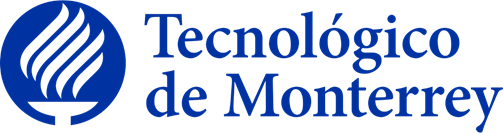

**Instituto Tecnológico y de Estudios Superiores de Monterrey**

TE3002B.502 

**Implementación de robótica Inteligente (Gpo 502)**

Semestre: febrero - junio 2023   

**Actividad:**

Actividad  8.2 - Modelado Cinematico de Piernas

**Alumno:**

		José Angel Ramírez Ramírez   	A01735529

**Profesor: Dr. Alfredo Garcia Suarez.**

Fecha de entrega: 26 de Mayo del 2023

## objetivos:

- **Crear** un nuevo repositorio con el nombre: **Actividad** **8.2 (Matriz de Transformación Homogénea T)**

- **Obtener** la matriz de  transformación **homogénea  T ** de los siguientes sistemas la cual relacione la posición y orientación del extremo del robot respecto a su sistema de referencia fijo (la base).

- **Implementar** el código requerido para generar el cálculo de las matrices **homogéneas (H1, H2, H3, etc.)** y la matriz de **transformación (T)** de cada sistema. Simulando cada una de las transformaciones desde la trama absoluta hasta la trama final.

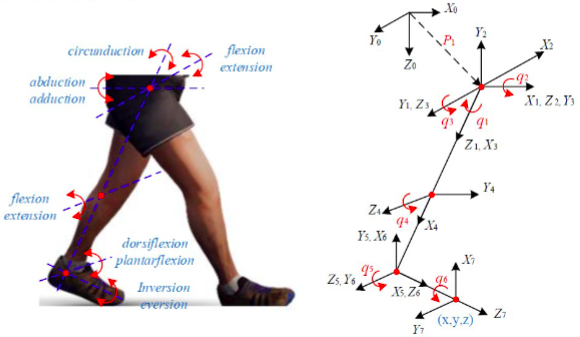

Para llevar a cabo esta actividad se sigue el mismo procedimiento declarado en la actividad 8.2:

- Se   calculan las rotaciones y/0 trasformaciones que se necesarias para obtener las  matrices de transformacion homogeneas hasta llegar a la trama final.

- Se declaran las longitudes entre las tramas que estan en distintos puntos, buscando que el estas longitudes hagan que la simulacion sea lo mas parecida a al sistema.

- Se calculan las matrices de transformacion homogeneas con los resultados obtenido en el primer paso

- Se calcula la matriz de transformacion homogenea global

- Se configura el plano de simulacion y dibujan las lineas del sistema sobre las que se mueven las tramas.

- Se simulan cada una de las tramas

- Se imprime la matriz de tranformacion homogenea global

- Por ultimo se imprime la matriz de transformacion homogenea global

De esta actividad lo unico que se puede resaltar es que durante la simulacion, hubo algunas tramas que se omitieron, pues al haber muchas tramas en este sistema, al simularlas todas algunos ejes se sobreponian, lo cual impidia que fuera visible el resultado esperado, sin embargo, esto no afecta en nada el resultado, ya que las tramas que se omitieron fueron las tramas primas ( ' ), que son las tramas intermedias necesarias que nos permitian llegar a una trama deseada. 

H1 = rotx(180)

H2 = rotx(-45)

H3 = rotx(-45)

H4 = roty(90)

H5 = rotx(90)

H6 =roty(-135) 

H7 = Trasx(3)

H8 = Trasz(3)

H9 = roty(45)

H10 = rotz(90)

H11 = rotz(90)

H12 = rotx(90)

H13 = Trasz(2.5)

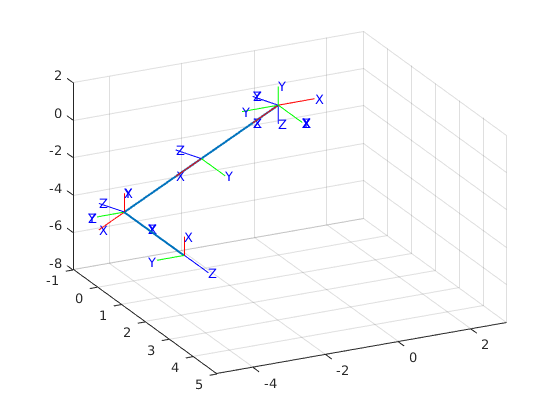

 %Limpieza de pantalla
clear all
close all
clc

%longitudes
l1 = 3;
l2 = 3;
l3 = 2.5; 


% Combinar matriz de rotación y matriz de traslación
H0 = SE3;

H1=SE3(rotx(deg2rad(180)), [0 0 0]);
H2=SE3(rotx(deg2rad(-45)), [0 0 0]);
H3=SE3(rotx(deg2rad(-45)), [0 0 0]);
H4=SE3(roty(deg2rad(90)),[0 0 0]);
H5=SE3(rotx(deg2rad(90)), [0 0 0]);
H6=SE3(roty(deg2rad(-135)), [0 0 0]);
H7=SE3(rotz(0), [l1 0 0]);
H8=SE3(rotz(0), [l2 0 0]);
H9=SE3(roty(deg2rad(45)), [0 0 0]);
H10=SE3(rotz(deg2rad(90)), [0 0 0]);
H11=SE3(rotz(deg2rad(90)), [0 0 0]);
H12=SE3(rotx(deg2rad(90)), [0 0 0]);
H13=SE3(rotz(0), [0 0 l3]);




H20= H1*H2;
H30= H20*H3; 
H40= H30*H4;
H50= H40*H5;
H60= H50*H6;
H70= H60*H7;
H80= H70*H8;
H90= H80*H9;
H100= H90*H10;
H110= H100*H11;
H120= H110*H12;
H130= H120*H13; 
%Matriz de transformación homogenea global de 13 a 0 

x=[0   0     0     2.5  ];
y=[0 -2.1 -4.25  -4.25 ];
z=[0 -2.1 -4.25  -4.25 ];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 5 -5 3 -8 2]); grid on;
hold on;

%Graficamos la trama absoluta o global 
%trplot(H0,'rgb','axis', [-1 5 -5 3 -8 2])

%Realizamos una animación para la siguiente trama
%%pause;
tranimate(H0, H1,'rgb','axis', [-1 5 -5 3 -8 2])
%Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H1, H20,'rgb','axis', [-1 5 -5 3 -8 2])
% %Realizamos una animación para la siguiente trama
 %pause;
 %tranimate(H20, H30,'rgb','axis', [-1 5 -5 3 -8 2])
 % %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H30, H40,'rgb','axis', [-1 5 -5 3 -8 2])
 % %Realizamos una animación para la siguiente trama
 %pause;
 %tranimate(H40, H50,'rgb','axis', [-1 5 -5 3 -8 2])
 % %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H50, H60,'rgb','axis', [-1 5 -5 3 -8 2])
  % %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H60, H70,'rgb','axis', [-1 5 -5 3 -8 2])
   % %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H70, H80,'rgb','axis', [-1 5 -5 3 -8 2])
    % %Realizamos una animación para la siguiente trama
 %pause;
 %tranimate(H80, H90,'rgb','axis', [-1 5 -5 3 -8 2])
    % %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H90, H100,'rgb','axis', [-1 5 -5 3 -8 2])
  % %Realizamos una animación para la siguiente trama
 %pause;
 %tranimate(H100, H110,'rgb','axis', [-1 5 -5 3 -8 2])
  % %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H110, H120,'rgb','axis', [-1 5 -5 3 -8 2])
  % %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H120, H130,'rgb','axis', [-1 5 -5 3 -8 2])
 
view([63.60 31.80])

disp(H130)

            0         0         1       2.5
    -2.22e-16        -1         0    -4.243
            1 -2.22e-16         0    -4.243
            0         0         0         1
